# Noise Analysis

Note we need some specs for the IMU as well as the IMU filter block

we do determine the following:

- Accelerometer noise (FilterBlock) -> line 210 ff

- Gyroscope noise (FilterBlock) -> line 210 ff

- Angle / Acc Velocity Random Walk

- Rate / Acc Acceleration Random Walk

- Bias Instability

Note that the first quantity is for the gyro analysis and the second for the accelerometer

But took standard values for the following:

- Gyroscope drift noise (Filter block) 

- Environmental Noise: LinAcc Noise and LinAccDecay factor (Filter block)

load('SensorReadingsForAnalysis.mat')
acc_init.data=logsout{5}.Values.Data; %acc
gyro_init.data=logsout{6}.Values.Data; %gyro


Fs=100;
t0 = 1/Fs;
theta = cumsum(acc_init.data(:,2), 1)*t0;


maxNumM = 100;
L = size(theta, 1);
maxM = 2.^floor(log2(L/2)); 
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

avar = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar(i,:) = sum( ...
        (theta(1+2*mi:L) - 2*theta(1+mi:L-mi) + theta(1:L-2*mi)).^2, 1);
end
avar = avar ./ (2*tau.^2 .* (L - 2*m));


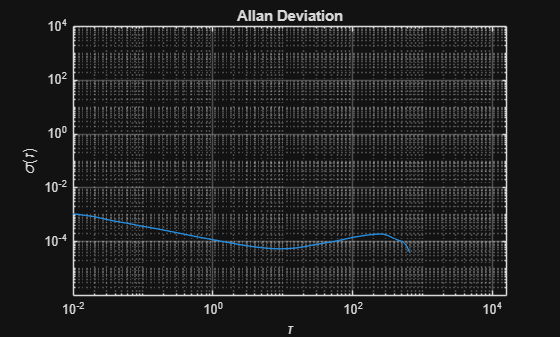

adev = sqrt(avar);

figure
loglog(tau, adev)
title('Allan Deviation')
xlabel('\tau');

ylabel('\sigma(\tau)')
grid on
axis equal


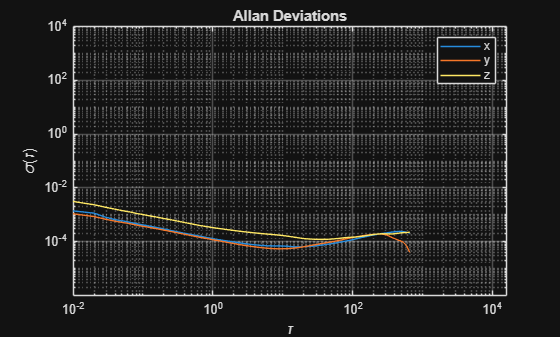

[avarFromFunc, tauFromFunc] = allanvar(acc_init.data, m, Fs);
adevFromFunc = sqrt(avarFromFunc);

clf
figure
loglog(tauFromFunc, adevFromFunc);
title('Allan Deviations')
xlabel('\tau')
ylabel('\sigma(\tau)')

legend('x', 'y','z')
grid on
axis equal

### Angle (Velocity) random walk

% vectorize the calculation for 3 channels
slope = -0.5;
logtau = log10(tau);
logadevFromFunc = log10(adevFromFunc);
dlogadevFromFunc = diff(logadevFromFunc) ./ diff(logtau);

i =     26    11    16


[~, i] = min(abs(dlogadevFromFunc - slope))

% Find the y-intercept of the line.
for n=1:3
    b(n) = logadevFromFunc(i(n),n) - slope*logtau(i(n));
end


b =    -3.8922   -3.9278   -3.4900


b

logN = slope*log(1) + b;

N = 1.0e-03 *

    0.1282    0.1181    0.3236


N = 10.^logN

%single component and visualization
slope = -0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope))

i = 11


% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i)

b = -3.9278


% Determine the angle random walk coefficient from the line.
logN = slope*log(1) + b;
N = 10^logN

N = 1.1808e-04

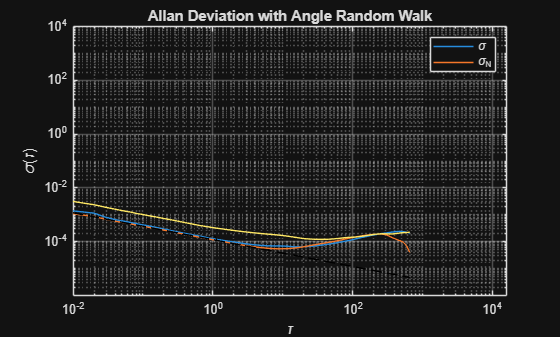

% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);
figure
loglog(tau, adevFromFunc, tau, lineN, 'k--', tauN, N, 'ko')
title('Allan Deviation with Angle Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N')
grid on
axis equal

### Rate (Acceleration) Random Walk

% vectorize the calculation for 3 channels
slope = 0.5;
logtau = log10(tau);
logadevFromFunc = log10(adevFromFunc);
dlogadevFromFunc = diff(logadevFromFunc) ./ diff(logtau);
[~, i] = min(abs(dlogadevFromFunc - slope))

i =     78    72    76



% Find the y-intercept of the line.
for n=1:3
    b(n) = logadevFromFunc(i(n),n) - slope*logtau(i(n));
end

b

b =    -4.9046   -4.8486   -4.8743


% Determine the rate random walk coefficient from the line.
logK = slope*log10(3) + b;
K = 10.^logK

K = 1.0e-04 *

    0.2157    0.2455    0.2313


%single component and visualization
slope = 0.5;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the rate random walk coefficient from the line.
logK = slope*log10(3) + b;
K = 10^logK

K = 2.4547e-05

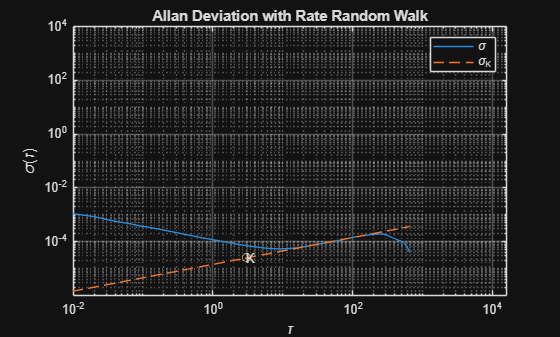


% Plot the results.
tauK = 3;
lineK = K .* sqrt(tau/3);
figure
loglog(tau, adev, tau, lineK, '--', tauK, K, 'o')
title('Allan Deviation with Rate Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_K')
text(tauK, K, 'K')
grid on
axis equal

### Bias Instability

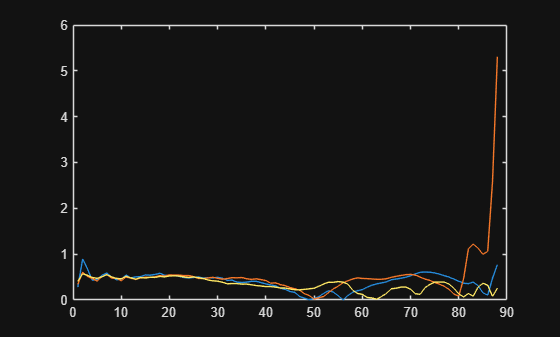

% vectorize the calculation for 3 channels
slope = 0;
logtau = log10(tau);
logadevFromFunc = log10(adevFromFunc);
dlogadevFromFunc = diff(logadevFromFunc) ./ diff(logtau);
plot(abs(dlogadevFromFunc - slope))

[~, i] = min(abs(dlogadevFromFunc(2:end,:) - slope)) %please do not take the first one...

i =     55    49    62


i=i+1;

% Find the y-intercept of the line.
for n=1:3
    b(n) = logadevFromFunc(i(n),n) - slope*logtau(i(n));
end

b

b =    -4.1970   -4.2681   -3.9187


% Determine the rate random walk coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10.^logB

B = 1.0e-03 *

    0.0956    0.0812    0.1815


%single component and visualization
slope = 0;
logtau = log10(tau);
logadev = log10(adev);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev(2:end) - slope));
i=i+1;

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the bias instability coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10^logB

B = 8.1195e-05

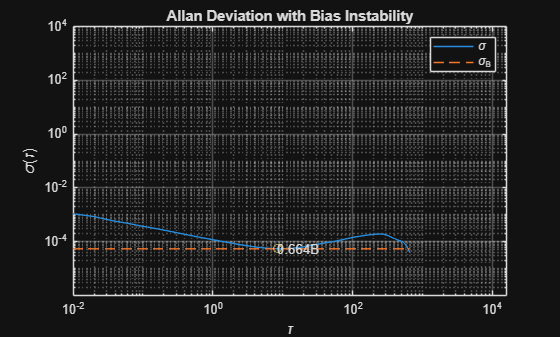


% Plot the results.
tauB = tau(i);
lineB = B * scfB * ones(size(tau));
figure
loglog(tau, adev, tau, lineB, '--', tauB, scfB*B, 'o')
title('Allan Deviation with Bias Instability')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_B')
text(tauB, scfB*B, '0.664B')
grid on
axis equal

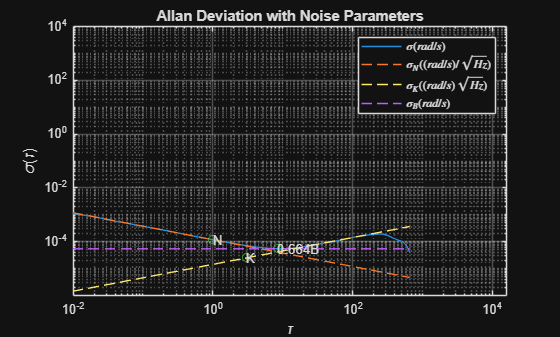

tauParams = [tauN, tauK, tauB];
params = [N, K, scfB*B];
figure
loglog(tau, adev, tau, [lineN, lineK, lineB], '--', ...
    tauParams, params, 'o')
title('Allan Deviation with Noise Parameters')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('$\sigma (rad/s)$', '$\sigma_N ((rad/s)/\sqrt{Hz})$', ...
    '$\sigma_K ((rad/s)\sqrt{Hz})$', '$\sigma_B (rad/s)$', 'Interpreter', 'latex')
text(tauParams, params, {'N', 'K', '0.664B'})
grid on
axis equal

generateSimulatedData = true;

if generateSimulatedData
    % Set the gyroscope parameters to the noise parameters determined 
    % above. Use single-sided noise to match the parameter scaling and 500
    % poles for the bias instability model to match the hardware output.
    numpoles = 500;
    gyro = gyroparams('NoiseDensity', N, 'RandomWalk', K, ...
        'BiasInstability', B, 'NoiseType', 'single-sided', ...
        'BiasInstabilityCoefficients', fractalcoef(numpoles));
    omegaSim = helperAllanVarianceExample(L, Fs, gyro);
else
    load('SimulatedSingleAxisGyroscope', 'omegaSim')
end

Running simulation 1 of 3 ...
Running simulation 2 of 3 ...
Running simulation 3 of 3 ...


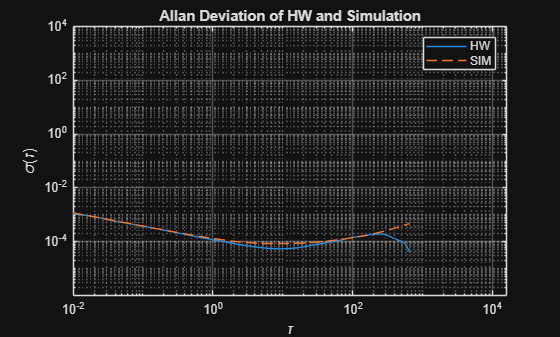

[avarSim, tauSim] = allanvar(omegaSim, 'octave', Fs);
adevSim = sqrt(avarSim);
adevSim = mean(adevSim, 2); % Use the mean of the simulations.

figure
loglog(tau, adev, tauSim, adevSim, '--')
title('Allan Deviation of HW and Simulation')
xlabel('\tau');
ylabel('\sigma(\tau)')
legend('HW', 'SIM')
grid on
axis equal

### Supporting function

function omegaSim = helperAllanVarianceExample(L, Fs, gyro, iters)
    %HELPERALLANVARIANCEEXAMPLE Helper function used by AllanVarianceExample
    %   OMEGASIM = HELPERALLANVARIANCEEXAMPLE(L, FS, GYRO) returns an L-by-3
    %   matrix OMEGASIM containing 3 different simulations of a stationary
    %   gyroscope with parameters GYRO and sampling rate FS.
    %     
    %   OMEGASIM = HELPERALLANVARIANCEEXAMPLE(L, FS, GYRO, ITERS) returns an 
    %   L-by-ITERS matrix OMEGASIM.
    %
    %   
    %   This function is for use with AllanVarianceExample only. It may be
    %   removed in the future.
    
    %   Copyright 2018-2019 The MathWorks, Inc.
    
    if nargin < 4
        iters = 3;
    end
    
    % Create stationary input.
    acc = zeros(L, 3);
    angvel = zeros(L, 3);
    
    omegaSim = zeros(L,iters);
    for i = 1:iters
        imu = imuSensor('SampleRate', Fs, 'Gyroscope', gyro, ...
        'RandomStream', 'mt19937ar with seed', 'Seed', i);
        fprintf('Running simulation %d of %d ...\n', i, iters);
        [~, gyroDataSim] = imu(acc, angvel);
        omegaSim(:,i) = gyroDataSim(:,1);
    end
end